# Practical Assignment 1: Accoustic localisation

Names:

NetIDs:

clear; clf; clc; close all;
addpath data
addpath functions

## 1. Calibration

load('calibration.mat')

### a) Measurement errors of each microphone at each sound pulse

The error at time step k for microphone j is given by:


$${\epsilon_{k,j} =\;y}_{k,j} -\frac{1}{8}\sum_{j=1}^8 y_{k,j}$$


% First get the means of all the TOA measurements
means = mean(y_toa')';
% Subtract the means (true value) to get the error of each sensor at each
% timestep
meas_errors = y_toa - means 

meas_errors = 1.0e-04 *

    0.1134    0.1134    0.1134   -0.1134    0.1134    0.1134   -0.1134   -0.3401
         0         0         0         0         0    0.2268         0   -0.2268
    0.0850    0.0850    0.0850    0.0850    0.0850    0.0850   -0.1417   -0.3685
   -0.0567    0.1701   -0.0567   -0.0567    0.1701    0.1701   -0.0567   -0.2834
         0         0         0         0         0    0.2268         0   -0.2268
    0.1134    0.1134    0.1134   -0.1134    0.1134    0.1134   -0.1134   -0.3401
   -0.0567    0.1701   -0.0567   -0.0567    0.1701    0.1701   -0.0567   -0.2834
    0.0283    0.0283    0.0283    0.0283    0.0283    0.0283    0.0283   -0.1984
    0.1134    0.1134    0.1134   -0.1134    0.1134    0.1134   -0.1134   -0.3401
   -0.0567    0.1701   -0.0567   -0.0567    0.1701    0.1701   -0.0567   -0.2834


Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(meas_errors,"1a"))

correct


### b) Measurement bias $b_i$ of each microphone

The bias for each microphone is the average of the errors for that microphine across all time steps. So if we have N time steps:


$$b_j =\frac{1}{N}\sum_{k=1}^N \epsilon_{k,j}$$


% Take the average error across all time steps to get the bias for each
% sensor
biases = mean(meas_errors)

biases = 1.0e-04 *

    0.0293    0.0870    0.0293   -0.0437    0.1023    0.1292   -0.0591   -0.2743


Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(biases,"1b"))

correct


### c) Variance $\sigma_i^2$of the measurement noise $e_i$ of each microphone

The variance of the measurement error for each microphone is given by:


$$\mathrm{Cov}\left\lbrace \epsilon_{k,j} \right\rbrace =\mathrm{Cov}\left\lbrace b_j +e_{k,j} \right\rbrace =\mathrm{Cov}\left\lbrace b_j \right\rbrace +\mathrm{Cov}\left\lbrace e_{k,j} \right\rbrace$$


However, the bias is deterministic, so it has 0 variance. Therefore, we are left with:


$$\mathrm{Cov}\left\lbrace \epsilon_{k,j} \right\rbrace =\mathrm{Cov}\left\lbrace e_{k,j} \right\rbrace =\sigma_e^2 =E\left\lbrace {\left(\epsilon_{k,j} -b_j \right)}^2 \right\rbrace$$


**FILL THIS IN**

% Use MATLAB's var function
vars = var(meas_errors)

vars = 1.0e-10 *

    0.4653    0.4484    0.4653    0.3583    0.4184    0.4052    0.3526    0.3448


Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(vars,"1c"))

correct


### d) Visualisation and interpretation of the measurement errors 

Uncomment the code sniplet below.

**Your text here:**

**FILL THIS IN**

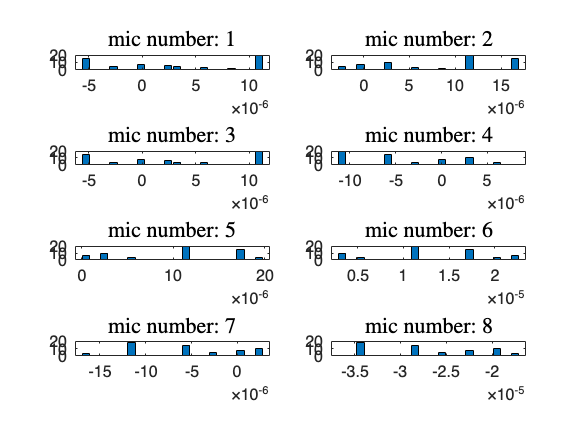

figure(1); clf;
for i = 1:size(y_toa,2)
    subplot(4,2,i);
    [N, l] = hist(meas_errors(:,i),20);
    Wb     = l(2)-l(1); % Bin widths
    Ny     = length(meas_errors(:,i)); % Nr of samples
    bar(l, N);
    title(['mic number: ',num2str(i)],'Interpreter','Latex','Fontsize',14)
end

## 2. Nonlinear least squares

load('experiment1.mat')
load('ground_truth1.mat')

### a) Nonlinear function $f$, and the noise covariance $\Sigma$

**Your text here** (*Please you the equation editor for equations)* **:**

### b) Jacobian

**Your text here** (*Please you the equation editor for equations)* **:**

### c) NLS algorithm

Implement the NLS algorithm to compute the position estimates **in the function templates** at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

%disp(testmyresult(@f,"2a1"))
%disp(testmyresult(@Jacobian,"2a2"))

### d) Computation of position estimates with NLS

Write your code in the box below, using the given initial state vector and maximum number of iterations.

% your code here
th0     = [0.12; 0.8; 70]; % initial state vector
maxiter = 100;             % maximum number of iterations


### e) Visualisation and interpretation

Uncomment the code below.

**Your text here****:**

%figure(2); clf;
%plotresults(th_nls(1:2,:),P_nls(1:2,1:2,:),mic_locations',ground_truth);

## 3. Kalman filtering 

### a) KF algorithm

Implement the Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

%disp(testmyresult(@measupdate_kf,"3a1"))
%disp(testmyresult(@timeupdate_kf,"3a2"))

### b) Computation of position estimates with KF

Write your code in the box below, using the given initial position and intial covariance matrix.

Tune $Q$ and $R_k$ as explained in the exercise pdf and comment on your choices.

**Your text here:**

% your code here


### c) Visualisation

Plot the mean and covariance of the **filtered** distribution. Uncomment the plot below.

**Your text here:**

%figure(3); clf;
%plotresults(p_kf,P_kf,mic_locations',ground_truth);

## 4. Extended Kalman fitering

### a) EKF algorithm

Implement the extended Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check wheather your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

%disp(testmyresult(@measupdate_ekf,"4a1"))
%disp(testmyresult(@timeupdate_ekf,"4a2"))

### b) Computation of position estimates with EKF

Tune $Q$ as explained in the exercise pdf and comment on your choices.

**Your text here:**

% your code here


### c) Visualisation

Plot the mean and covariance of the **filtered** distribution.

**Your text here:**

%figure(4); clf;
%plotresults(th_ekf(1:2,:),P_ekf(1:2,1:2,:),mic_locations',ground_truth);

# Copy all your functions below this text before exporting to PDF!! 

## Functions

NLS

KF

EKF